load('D:\Bezmen\PavelSheptuhin\GenV');

l = 2;
Gen_s = CreateABParameterGenerator({'l', 'cos', l, [1, 0, 0]; 'l', 'sin', l, [0, 1, 0]});
bm = 1e-6;

x0 = 3;
y0 = 3;
z0 = 0;
r = 3;

n = 75;
[x, y, z] = meshgrid(linspace(x0 - r, x0 + r, n), linspace(y0 - r, y0 + r, n), linspace(z0 - r, z0 + r, n));
%{
r = linspace(1e-4, 10, 200);
aalf = deg2rad(45);
bbet = deg2rad(89.99);
y = r*sin(aalf)*cos(bbet);
x = r*cos(aalf)*cos(bbet);
z = r*sin(bbet);
%}
alf = repmat(1e-3, size(x));
bet = repmat(1e-3, size(y));
gam = repmat(1e-3, size(z));
%{
figure;
res = CalcAmplEr(x, y, z, alf, bet, gam, bm, l, GenV, Gen_s);
plot(r, res{4})
ylim([-100, 100])

figure;
plot(r, res{1}, r, res{2})
legend(["Диполь", "Соленоид"])
ylim([0, 1e-6])
%}
relativeError = CalcRelativeError(x, y, z, alf, bet, gam, bm, l, GenV, Gen_s);
relativeAmplErr = CalcAmplEr(x, y, z, alf, bet, gam, bm, l, GenV, Gen_s);
ere2 = CalcRelativeError(repmat(0.01,[1 n]), repmat(0.01,[1 n]), linspace(0.01, 5, n), zeros(1,n), zeros(1,n), zeros(1,n), bm, l, GenV, Gen_s);

ab = RelativeErrrorab(relativeAmplErr{5}, relativeAmplErr{6});

Построение графиков.

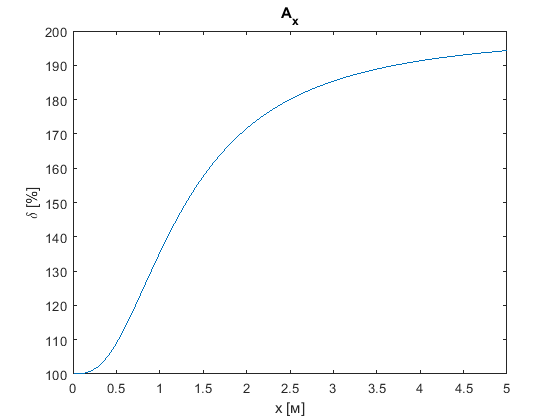

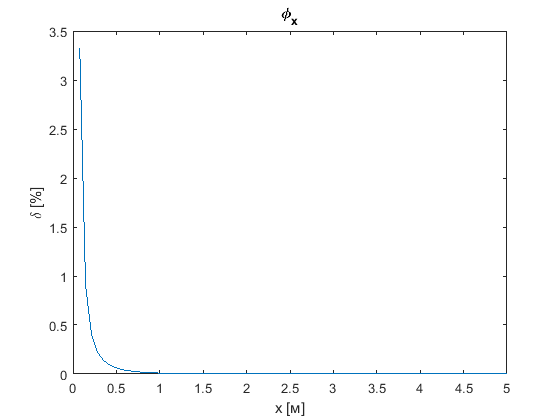

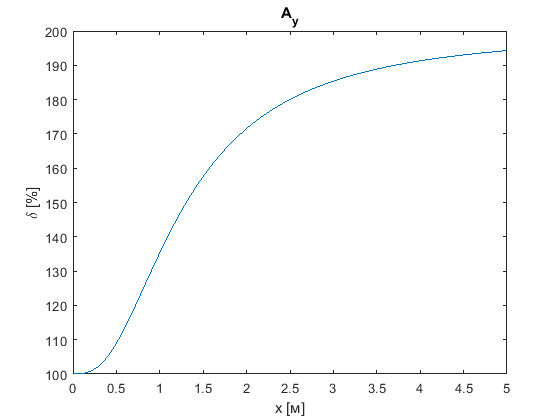

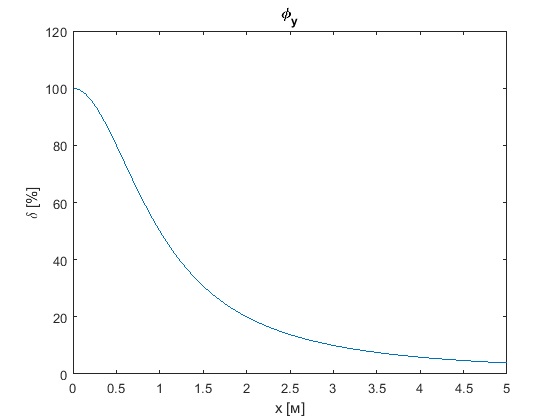

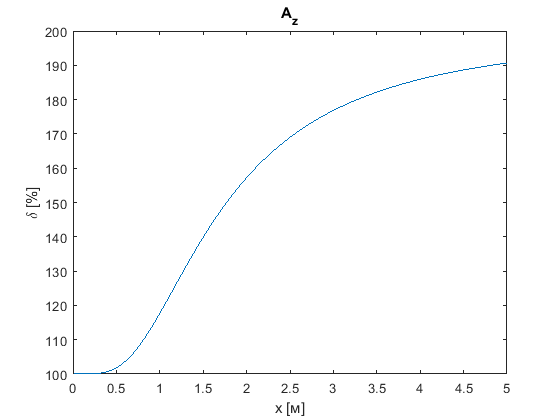

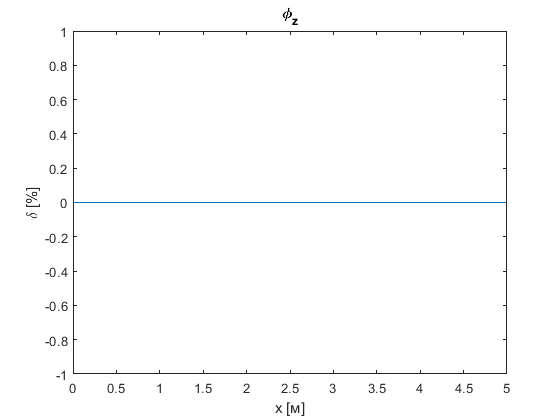

xslice = 0;   
yslice = 0;
zslice = 0;
zindex = 32;

titlesTexts = ["A_x", "\phi_x", "A_y", "\phi_y", "A_z", "\phi_z"];
%{
for i = 1:6
    figure;
    slice(x,y,z, relativeError{1, i}, xslice, yslice, zslice)
    xlabel('x [м]'); ylabel('y [м]'); zlabel('z [м]');
    title(titlesTexts(i))
        
    figure;
    surf(x(:,:,zindex), y(:,:,zindex), relativeError{1, i}(:,:,zindex), "EdgeColor","none")
    set(gca, 'ZScale', 'log');
    xlabel('x [м]'); ylabel('y [м]');
    title(titlesTexts(i) + " z = " + num2str(z(1,1,zindex)))
end
%}

for i = 1:6
    figure;
    plot(linspace(0.01, 5, n), ere2{1, i})
    xlabel('x [м]'); ylabel('\delta [%]');
    title(titlesTexts(i))
end

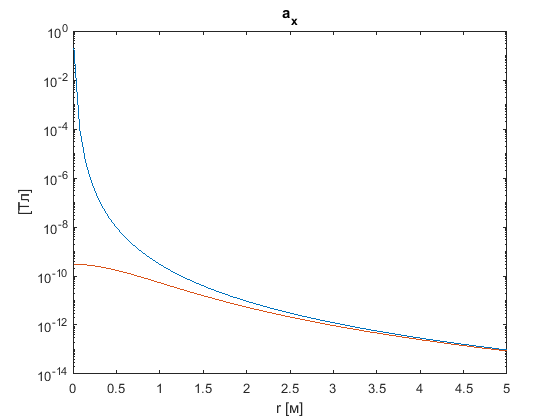

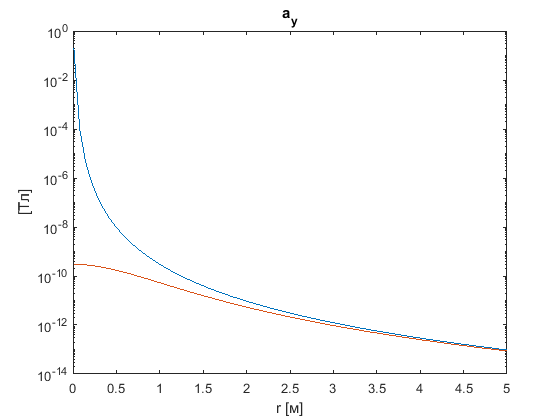

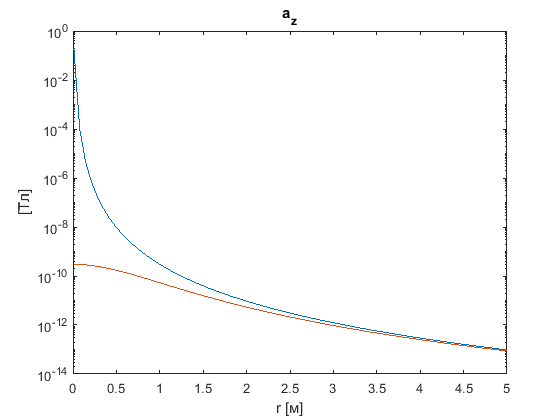

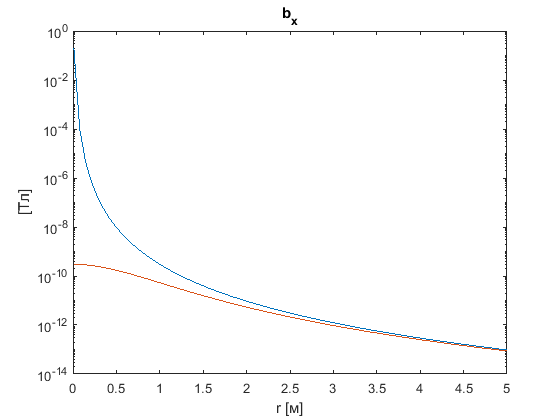

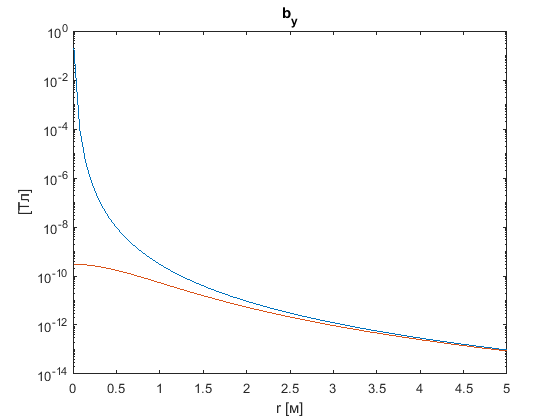

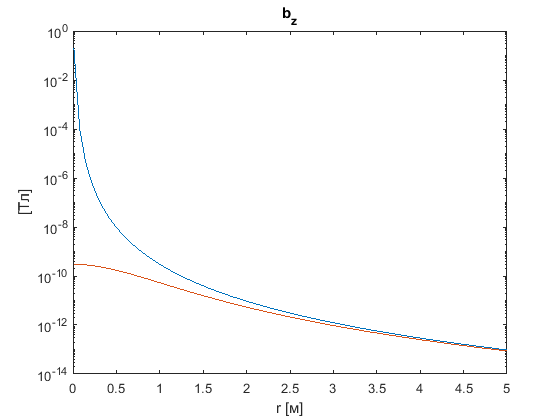

titlesTexts = ["a_x", "a_y", "a_z", "b_x", "b_y", "b_z"];
for i = 1:6
    figure;
    plot(linspace(0.01, 5, n), ere2{2, i}, linspace(0.01, 5, n), ere2{3, i})
    set(gca, 'YScale', 'log');
    xlabel('r [м]'); ylabel('[Тл]');
    title(titlesTexts(i))
end

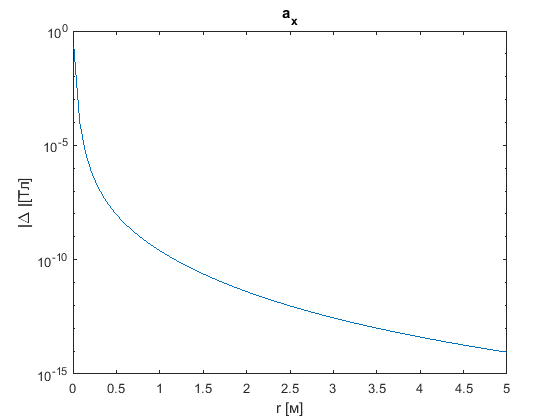

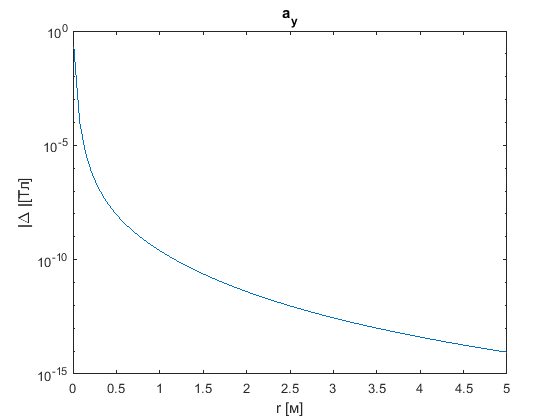

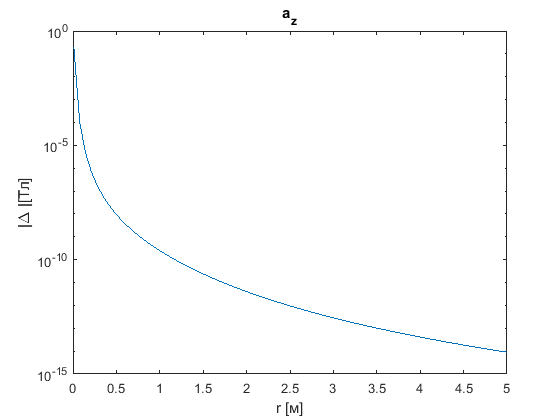

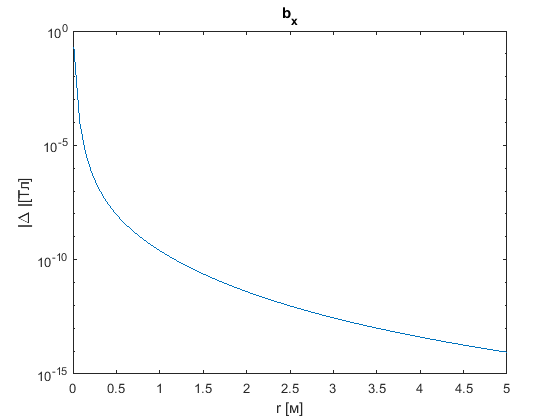

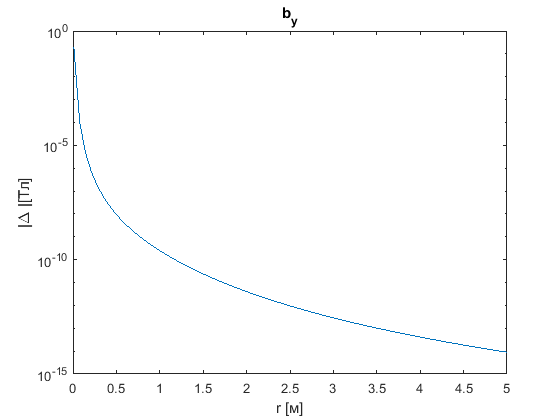

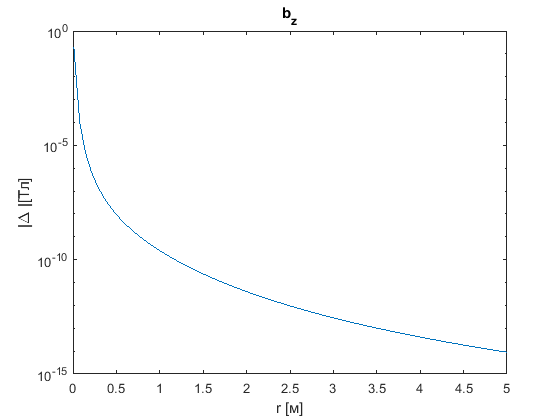

for i = 1:6
    figure;
    plot(linspace(0.01, 5, n), abs(ere2{2, i} - ere2{3, i}))
    set(gca, 'YScale', 'log');
    xlabel('r [м]'); ylabel('|\Delta |[Тл]');
    title(titlesTexts(i))
end

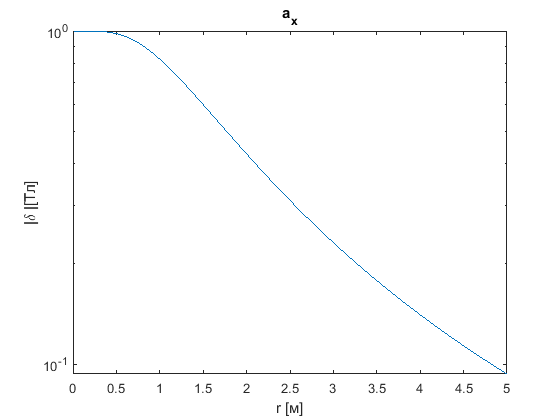

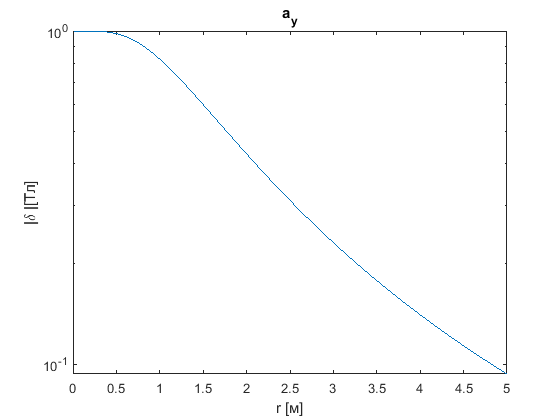

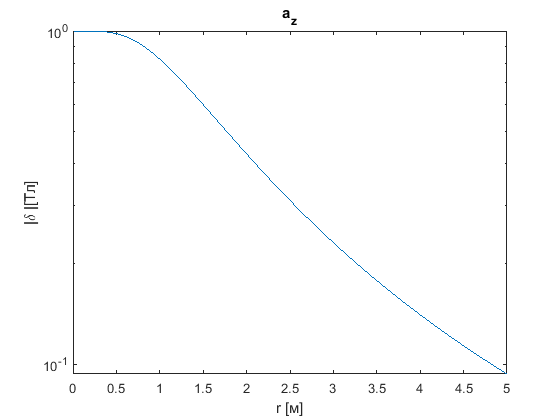

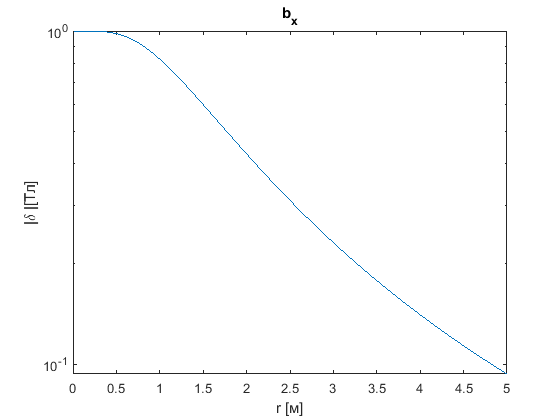

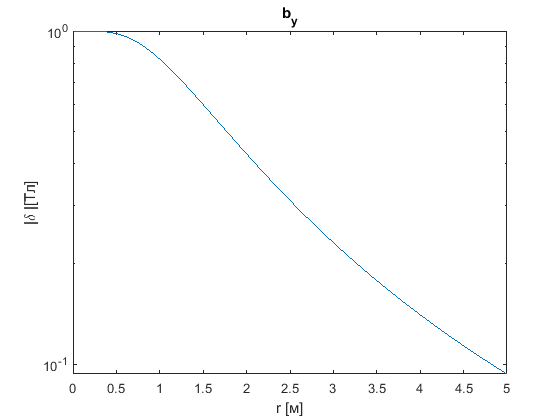

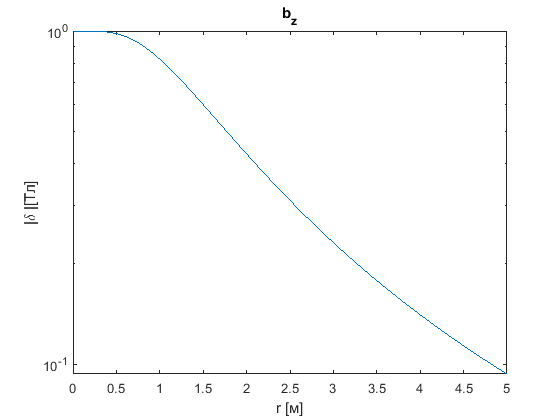

for i = 1:6
    figure;
    plot(linspace(0.01, 5, n), abs((ere2{2, i} - ere2{3, i})./ere2{2, i}))
    set(gca, 'YScale', 'log');
    xlabel('r [м]'); ylabel('|\delta |[Тл]');
    title(titlesTexts(i))
end

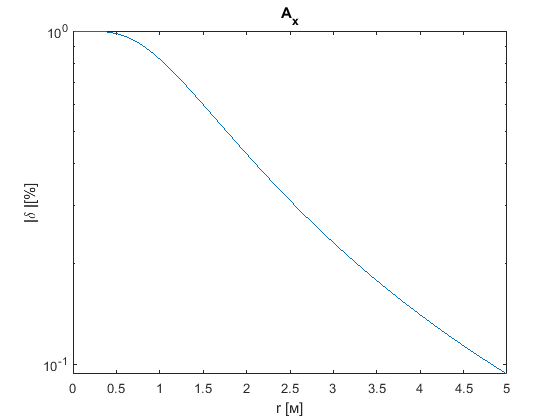

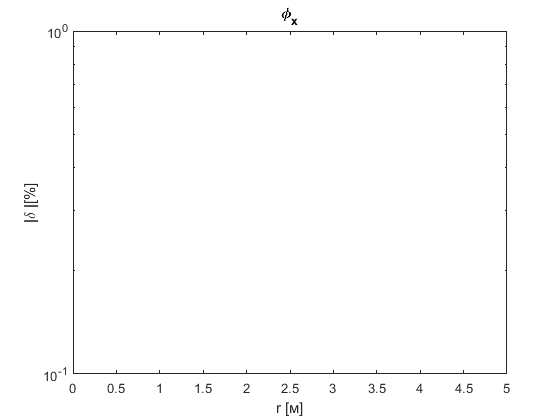

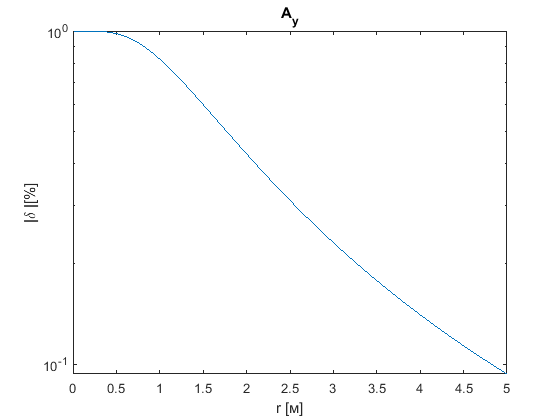

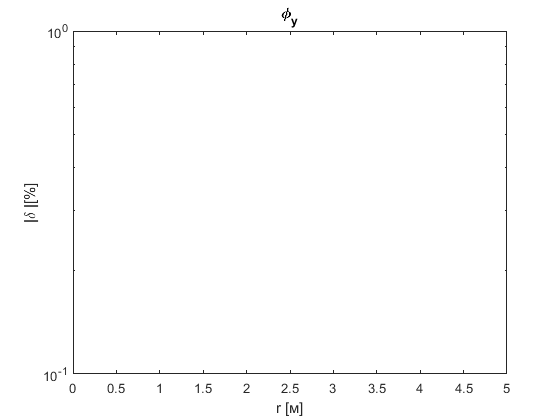

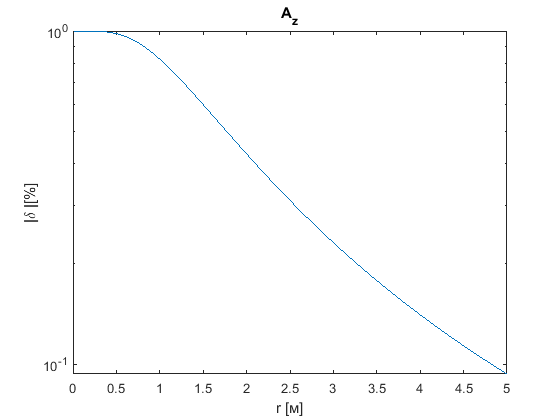

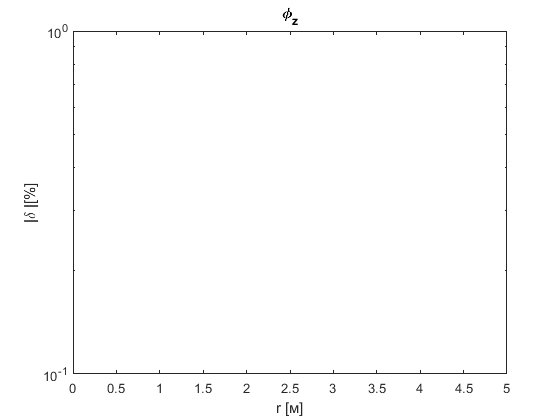


titlesTexts = ["A_x", "\phi_x"; "A_y", "\phi_y"; "A_z", "\phi_z"];

amplPhase_dip = AmplAngle(ere2{2, 1}, ere2{2, 2}, ere2{2, 3}, ere2{2, 4}, ere2{2, 5}, ere2{2, 6});
amplPhase_sol = AmplAngle(ere2{3, 1}, ere2{3, 2}, ere2{3, 3}, ere2{3, 4}, ere2{3, 5}, ere2{3, 6});
for i = 1:3
    for j = 1:2
        figure;
        plot(linspace(0.01, 5, n), abs((amplPhase_dip{i, j} - amplPhase_sol{i, j})./amplPhase_dip{i, j}))
        set(gca, 'YScale', 'log');
        xlabel('r [м]'); ylabel('|\delta |[%]');
        title(titlesTexts(i,j))
    end
end

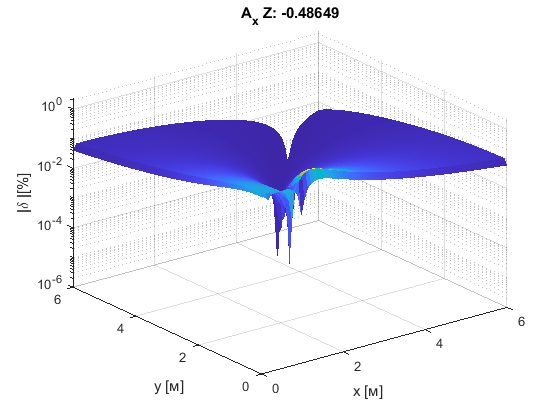

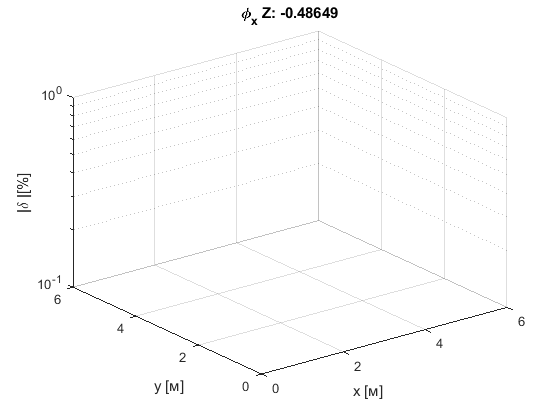

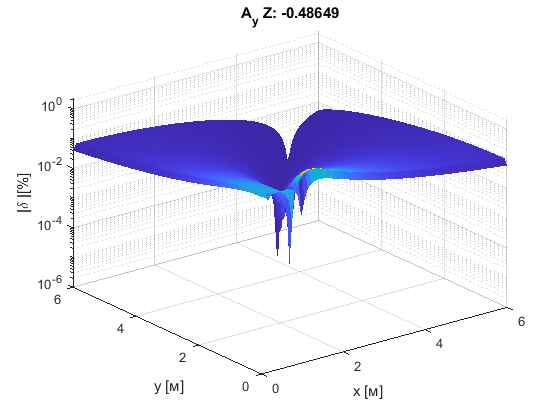

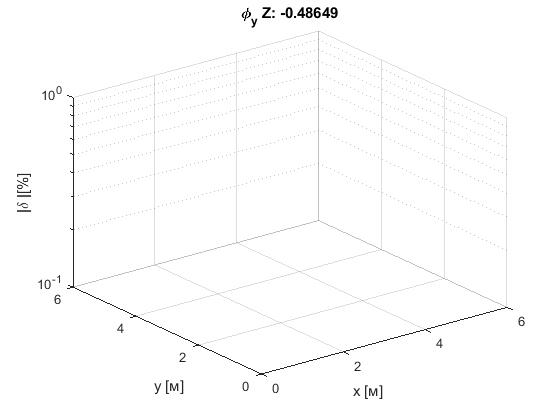

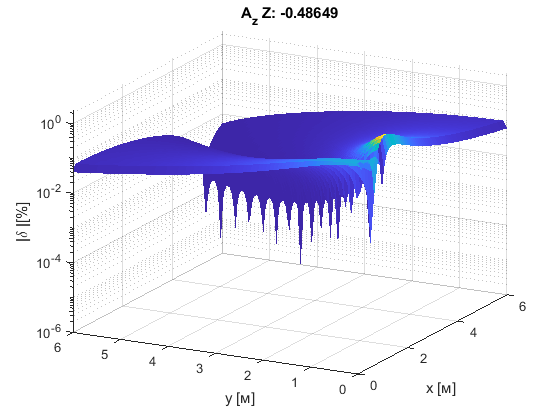

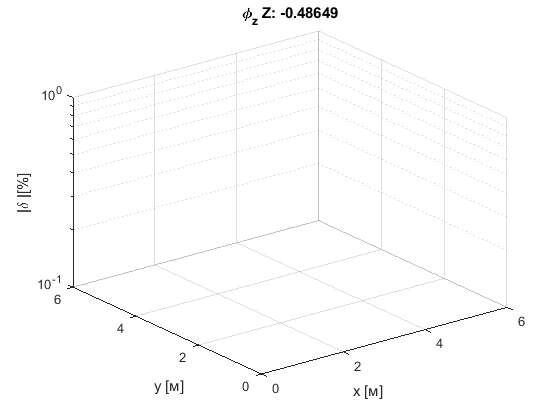


amplPhase_dip = AmplAngle(relativeError{2, 1}, relativeError{2, 2}, relativeError{2, 3}, relativeError{2, 4}, relativeError{2, 5}, relativeError{2, 6});
amplPhase_sol = AmplAngle(relativeError{3, 1}, relativeError{3, 2}, relativeError{3, 3}, relativeError{3, 4}, relativeError{3, 5}, relativeError{3, 6});
reler = {zeros(size(amplPhase_dip{1,1})), zeros(size(amplPhase_dip{1,1})); zeros(size(amplPhase_dip{1,1})), zeros(size(amplPhase_dip{1,1})); zeros(size(amplPhase_dip{1,1})), zeros(size(amplPhase_dip{1,1}))};
for i = 1:3
    for j = 1:2
        figure;
        reler{i,j} = abs((amplPhase_dip{i, j} - amplPhase_sol{i, j})./amplPhase_dip{i, j});
        surf(x(:,:,zindex), y(:,:,zindex), abs((amplPhase_dip{i, j}(:,:,zindex) - amplPhase_sol{i, j}(:,:,zindex))./amplPhase_dip{i, j}(:,:,zindex)), "EdgeColor", "none")
        set(gca, 'ZScale', 'log');
        xlabel('x [м]'); ylabel('y [м]'); zlabel('|\delta |[%]');
        title(titlesTexts(i, j) + " Z: " + num2str(z(1,1,zindex)))
    end
end

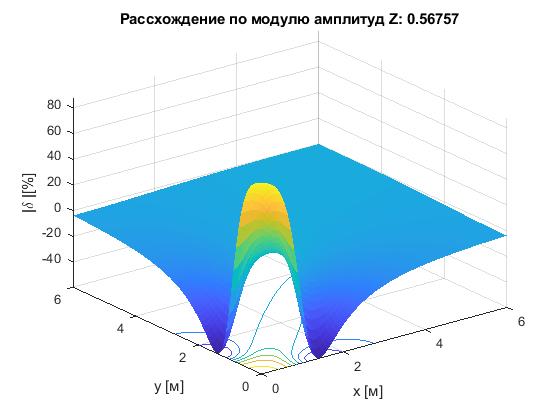


%%Рассчитываем расхождение по модулю 
zindex = 45;
norm_dip = sqrt(amplPhase_dip{1, 1}.^2+amplPhase_dip{2, 1}.^2+amplPhase_dip{3, 1}.^2);
norm_sol = sqrt(amplPhase_sol{1, 1}.^2+amplPhase_sol{2, 1}.^2+amplPhase_sol{3, 1}.^2);
reler2 = abs((norm_dip-norm_sol)./norm_dip);
surfc(x(:,:,zindex), y(:,:,zindex), relativeAmplErr{4}(:,:,zindex), "EdgeColor", "none")
%set(gca, 'ZScale', 'log');
xlabel('x [м]'); ylabel('y [м]'); zlabel('|\delta |[%]');
title("Рассхождение по модулю амплитуд Z: " + num2str(z(1,1,zindex)))


figure;
slobj =  slice(x, y, z, relativeAmplErr{4}, xslice, yslice, zslice)

slobj =   3×1 Surface array:

  Surface
  Surface
  Surface


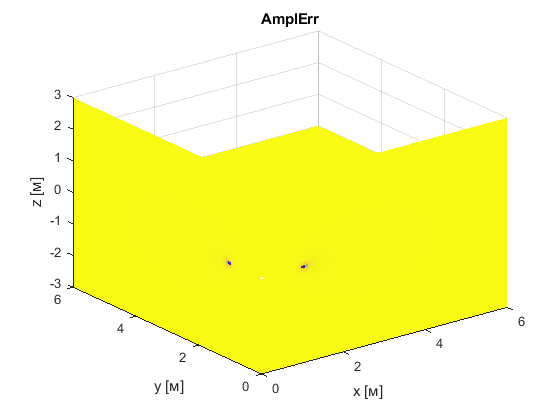

for ind = 1:3
    slobj(ind).EdgeColor = 'none';
end
xlabel('x [м]'); ylabel('y [м]'); zlabel('z [м]');
title('AmplErr')

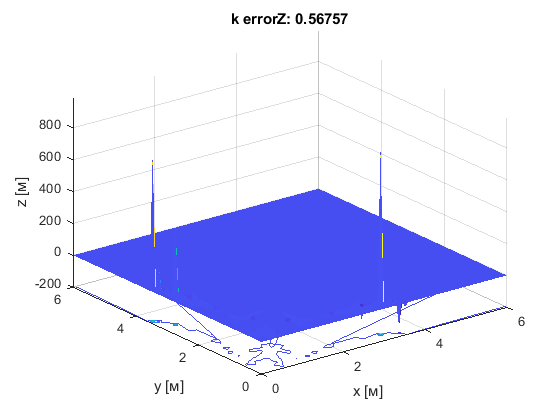



figure;
surfc(x(:,:,zindex), y(:,:,zindex), ab(:,:,zindex), "EdgeColor", "none")
xlabel('x [м]'); ylabel('y [м]'); zlabel('z [м]');
title("k errorZ: " + num2str(z(1,1,zindex)))

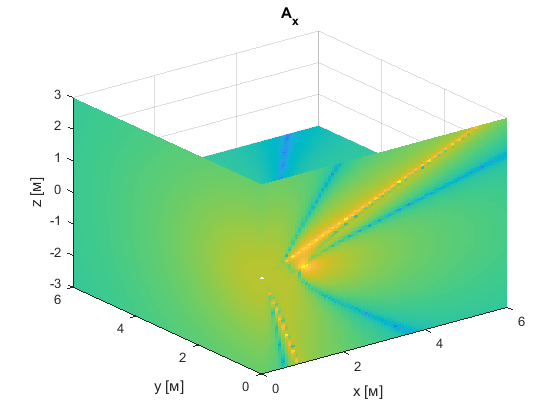

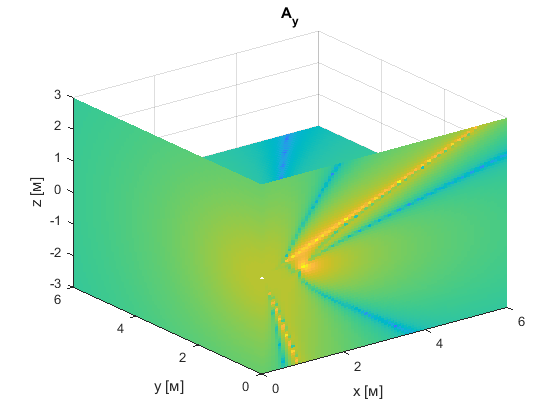

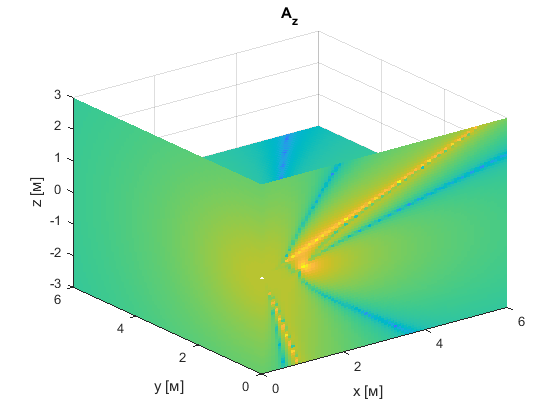

%%% ------------------------------------------------------ %%%

for i = 1:3
    for j = 1
        figure;
        slobj = slice(x,y,z, log10(reler{i, j}), xslice, yslice, zslice);
        for ind = 1:3
            slobj(ind).EdgeColor = 'none';
        end
        xlabel('x [м]'); ylabel('y [м]'); zlabel('z [м]');
        title(titlesTexts(i, j)) 
    end
end

function errs = CalcRelativeError(x, y, z, alf, bet, gam, bm, l, Gen_d, Gen_s)
ax = zeros(size(x));
phx = zeros(size(x));
ay = zeros(size(x));
phy = zeros(size(x));
az = zeros(size(x));
phz = zeros(size(x));
dip = {zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x))};
sol = {zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x)), zeros(size(x))};
for i = 1:numel(x)
    dipole_v = Gen_d(bm, alf(i), bet(i), gam(i), y(i), x(i), z(i));
    sol_v =  Gen_s(bm/l, alf(i), bet(i), gam(i), y(i), x(i), z(i));
    %er_v = 100*abs((dipole_v - Gen_s(bm/l, alf(i), bet(i), gam(i), y(i), x(i), z(i)))./dipole_v);
    for j = 1:6
        dip{j}(i) = dipole_v(1);
        sol{j}(i) = sol_v(1);
    end
    ax(i) = 100 * (sqrt(dipole_v(1,1)^2 + dipole_v(1,2)^2) + sqrt(sol_v(1,1)^2 + sol_v(1,2)^2))/sqrt(dipole_v(1,1)^2 + dipole_v(1,2)^2);
    phx(i) = 100 * abs((atan(dipole_v(1,2)/dipole_v(1,1)) - atan(sol_v(1,2)/sol_v(1,1)))/atan(dipole_v(1,2)/dipole_v(1,1)));
    ay(i) = 100 * (sqrt(dipole_v(2, 1)^2 + dipole_v(2, 2)^2) + sqrt(sol_v(2, 1)^2 + sol_v(2, 2)^2))/sqrt(dipole_v(2, 1)^2 + dipole_v(2, 2)^2);
    phy(i) = 100 * abs((atan(dipole_v(2, 2)/dipole_v(2, 1)) - atan(sol_v(2, 2)/sol_v(2, 1)))/atan(dipole_v(2, 2)/dipole_v(2, 1)));
    az(i) = 100 * (sqrt(dipole_v(3, 1)^2 + dipole_v(3, 2)^2) + sqrt(sol_v(3, 1)^2 + sol_v(3, 2)^2))/sqrt(dipole_v(3, 1)^2 + dipole_v(3, 2)^2);
    phz(i) = 100 * abs((atan(dipole_v(3, 2)/dipole_v(3, 1)) - atan(sol_v(3, 2)/sol_v(3, 1)))/atan(dipole_v(3, 2)/dipole_v(3, 1)));
    
    if ax(i) > 1000
        ax(i) = nan;
    end
    if phx(i) > 1000
        phx(i) = nan;
    end
    if ay(i) > 1000
        ay(i) = nan;
    end
    if phy(i) > 1000
        phy(i) = nan;
    end
    if az(i) > 1000
        az(i) = nan;
    end
    if phz(i) > 1000
        phz(i) = nan;
    end
end
    errs = {ax, phx, ay, phy, az, phz; dip{:}; sol{:}};
end


function amplPhase = AmplAngle(ax, ay, az, bx, by, bz)
aamplx = zeros(size(ax));
pphx = zeros(size(ax));
aamply = zeros(size(ax));
pphy = zeros(size(ax));
aamplz = zeros(size(ax));
pphz = zeros(size(ax));

for i = 1:numel(ax)
    aamplx(i) = sqrt(ax(i)^2 + bx(i)^2);
    pphx(i) = atan(bx(i)/ax(i));
    aamply(i) = sqrt(ay(i)^2 + by(i)^2);
    pphy(i) = atan(by(i)/ay(i));
    aamplz(i) = sqrt(az(i)^2 + bz(i)^2);
    pphz(i) = atan(bz(i)/az(i));
end
amplPhase = {aamplx, pphx; aamply, pphy; aamplz, pphz};
end

function err = CalcAmplEr(x, y, z, alf, bet, gam, bm, l, gen_d, gen_s)
arguments
    x  double
    y  double
    z  double
    alf  double
    bet  double
    gam  double
    bm (1,1) double
    l (1,1) double
    gen_d (1, 1) function_handle
    gen_s (1, 1) function_handle
end

if ~(numel(x) == numel(y) && numel(x) == numel(z) && numel(x) == numel(alf) && numel(x) == numel(bet) && numel(x) == numel(gam))
    error("Не подходящая размерность аргументов.")
end
dip = zeros(3,2);
sol = zeros(3,2);
ampl_dip = zeros(3,2);
ampl_sol = zeros(3,2);
abs_er = zeros(size(x));
rel_er = zeros(size(x));
d = zeros(size(x));
s = zeros(size(x));
dipp = zeros([3, 2, size(x)]);
soll = zeros([3, 2, size(x)]);
for i = 1:numel(x)
    dip = gen_d(bm, alf(i), bet(i), gam(i),  y(i), x(i), z(i));
    sol = gen_s(bm/l, alf(i), bet(i), gam(i), y(i), x(i), z(i) );
    
    dipp(:, :, i) = dip;
    soll(:, :, i) = sol;
    
    ampl_dip = AmplAngle(dip(1), dip(2), dip(3), dip(4), dip(5), dip(6));
    ampl_sol = AmplAngle(sol(1), sol(2), sol(3), sol(4), sol(5), sol(6));
    d(i) = sqrt(sum([ampl_dip{:,1}].^2));
    s(i) = sqrt(sum([ampl_sol{:,1}].^2));
    abs_er(i) = sqrt(sum([ampl_dip{:,1}].^2)) - sqrt(sum([ampl_sol{:,1}].^2));
    rel_er(i) = 100*abs_er(i)./sqrt(sum([ampl_dip{:,1}].^2));
end
err = {d, s, abs(abs_er), rel_er, dipp, soll};
end





function err = RelativeErrrorab(dip, sol)
arguments
    dip(3,2,:,:,:) double
    sol(3,2,:,:,:) double
end
sz = size(dip);
sz = sz(3:end);
er = zeros(sz);
for i = 1:sz(1)
    for j = 1:sz(2)
        for k = 1:sz(3)
            kx = sqrt((dip(1,1,i, j, k).^2 + dip(1,2,i, j, k).^2)./(sol(1,1,i, j, k).^2 + sol(1,2,i, j, k).^2));
            ky = sqrt((dip(2,1,i, j, k).^2 + dip(2,2,i, j, k).^2)./(sol(2,1,i, j, k).^2 + sol(2,2,i, j, k).^2));
            kz = sqrt((dip(3,1,i, j, k).^2 + dip(3,2,i, j, k).^2)./(sol(3,1,i, j, k).^2 + sol(3,2,i, j, k).^2));
            kn = sqrt( sum(dip(:,:,i, j, k).^2, 'all')/sum(sol(:,:,i, j, k).^2, 'all') );
            
            er(i, j, k) = ((kx^(2))*( sol(1,1,i, j, k)*sol(1,2,i, j, k) ) + (ky^(2))*( sol(2,1,i, j, k)*sol(2,2,i, j, k) ) + (kz^(2))*( sol(3,1,i, j, k)*sol(3,2,i, j, k) ) - (kn^(2))*( sol(1, 1, i, j, k)*sol(1, 2, i, j, k) ) - (kn^(2))*( sol(2,1,i, j, k)*sol(2,2,i, j, k) ) - (kn^(2))*( sol(3,1,i, j, k)*sol(3,2,i, j, k) )) / ((kx^(2))*( sol(1,1,i, j, k)*sol(1,2,i, j, k) ) + (ky^(2))*( sol(2,1,i, j, k)*sol(2,2,i, j, k) ) + (kz^(2))*( sol(3,1,i, j, k)*sol(3,2,i, j, k) ) );    
        end
    end
end
err = er;
end